# Tutorial toolbox modelamiento de nicho

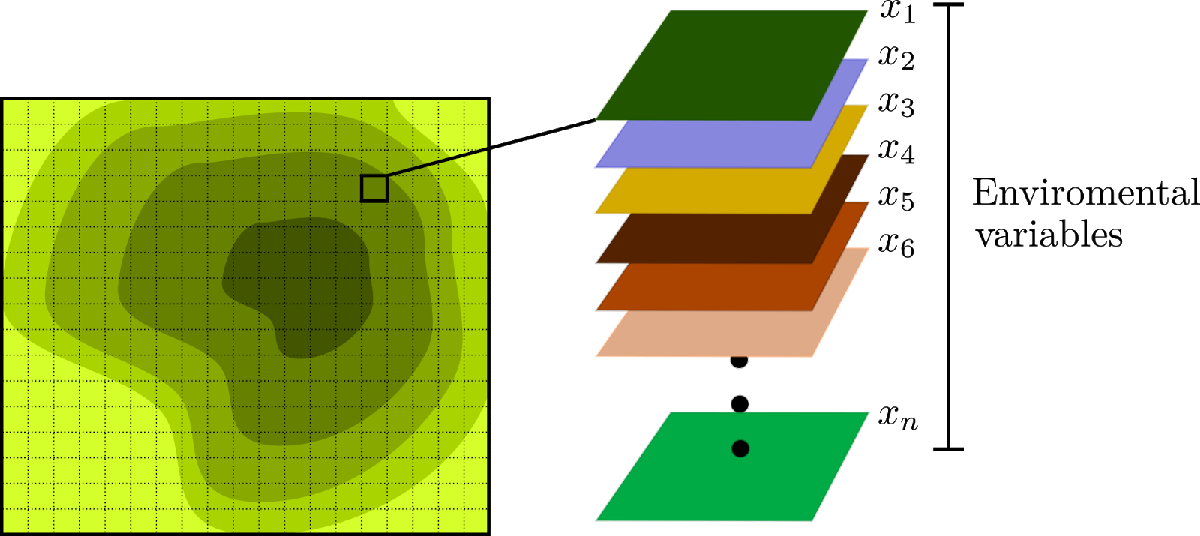

doc='../data/records/final_dataset.csv';%Ruta al documento de texto con los registros
layerfolder='../data/layers/';%route to folder with ambiental data
show=true;%para mostrar todas las figuras
data = bnm_prep(doc,layerfolder,show)

----Reading layers----


Elapsed time is 9.775358 seconds.
--Sampling f(z) with 306593 samples--


----Modeling----


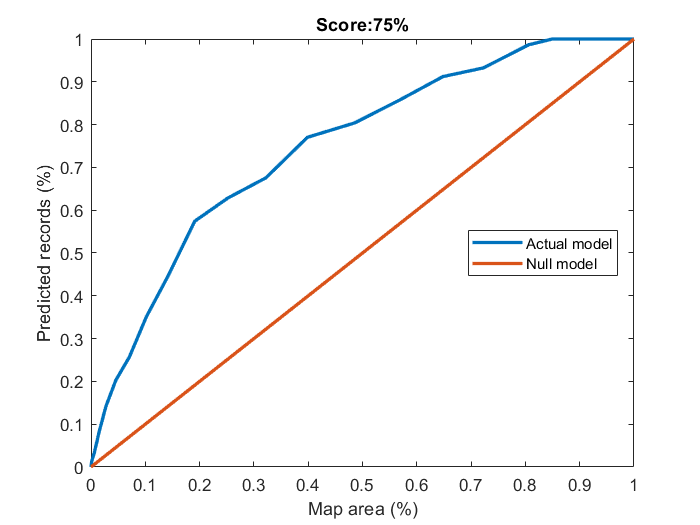

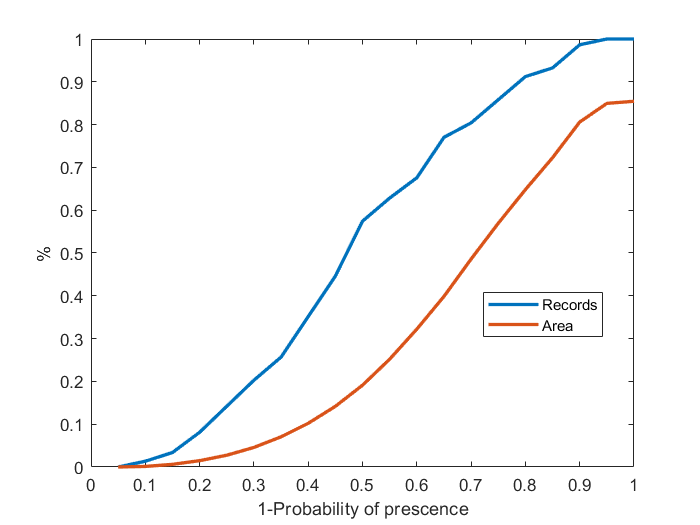

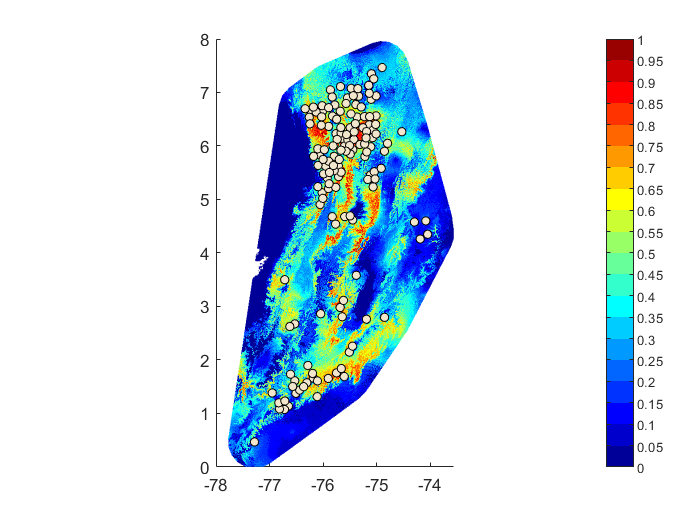

Elapsed time is 1.326501 seconds.


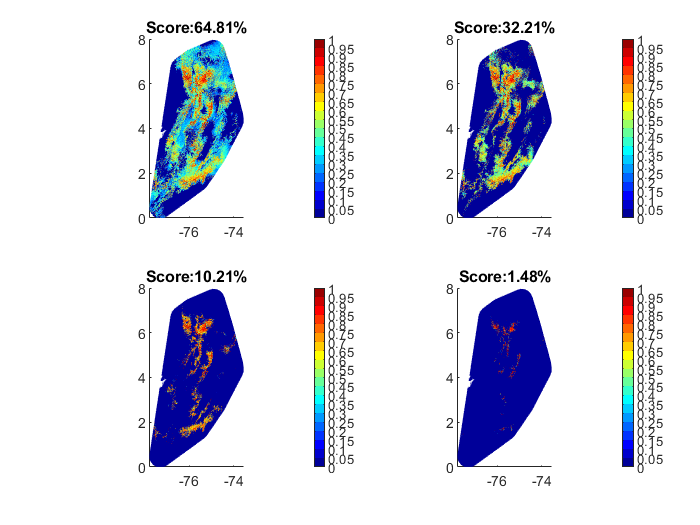

data = struct with fields:
         Tdata: [100×11 table]
    Indicators: [1 4 6 7 12 13 14]
          Vars: [1 4 6 12]
            T2: [148×22 table]
             Z: [956×507×19 double]
             R: [3×2 double]
           Map: [956×507 double]
      Response: [484692×11 double]
      Minimize: 0.7957
        Method: 4


data = bnm_modeling(data,[],show)

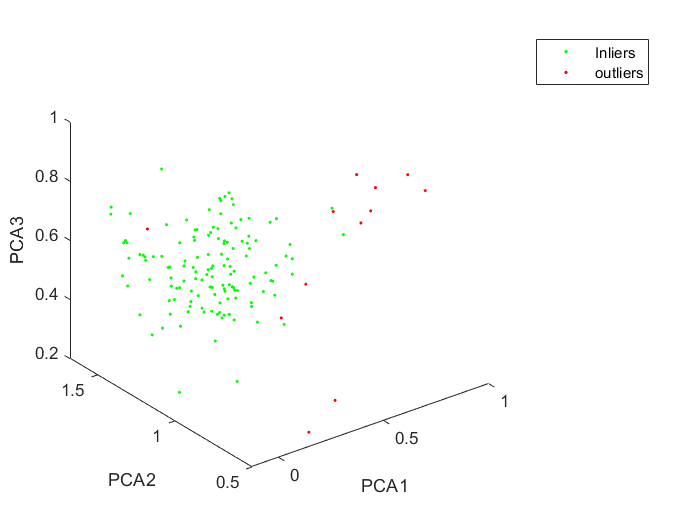

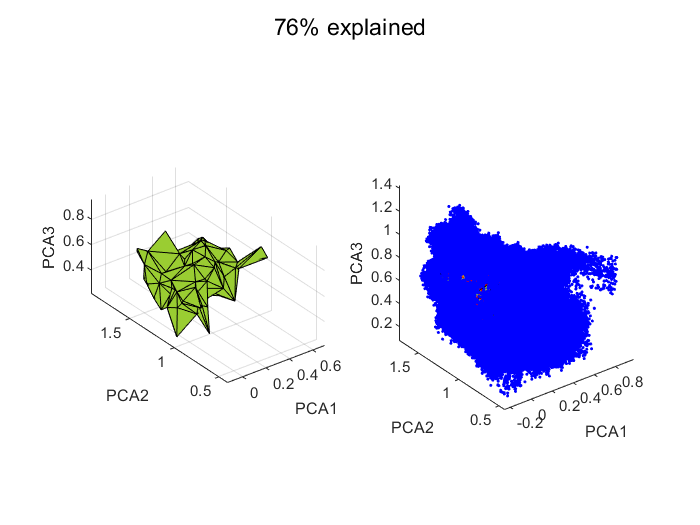

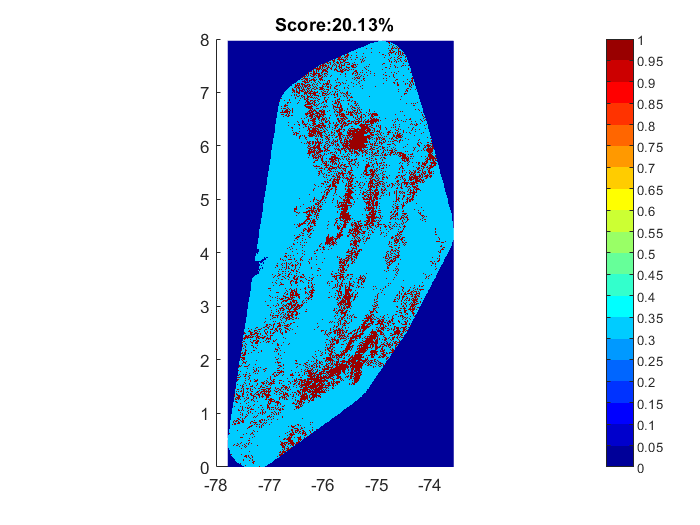

data = struct with fields:
         Tdata: [100×11 table]
    Indicators: [1 4 6 7 12 13 14]
          Vars: [1 4 6 12]
            T2: [148×22 table]
             Z: [956×507×19 double]
             R: [3×2 double]
        MapPca: [956×507 double]
      ScorePca: 20.1345


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data,show,outlier,outlier2)


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100          0.2823          0.3074        0
    1             200          0.2676          0.3106        0
    2             300           0.264          0.2862        0
    3             400          0.2595          0.2776        0
    4             500          0.2565          0.2693        0
    5             600          0.2548          0.2643        0
    6             700          0.2547          0.2625        0
    7             800          0.2547          0.2625        1
    8             900          0.2547          0.2612        2
    9            1000          0.2547          0.2615        3
   10            1100          0.2545          0.2603        0
   11            1200          0.2529          0.2612        0
   12            1300          0.2529          0.2631        1
   13            1400          0.2529          0

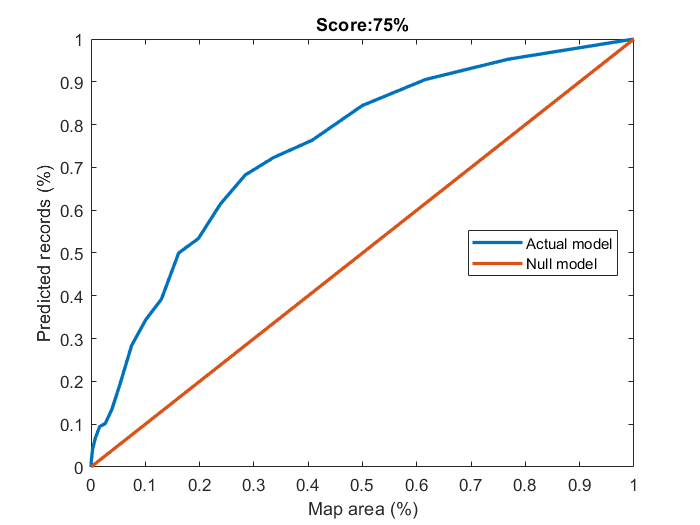

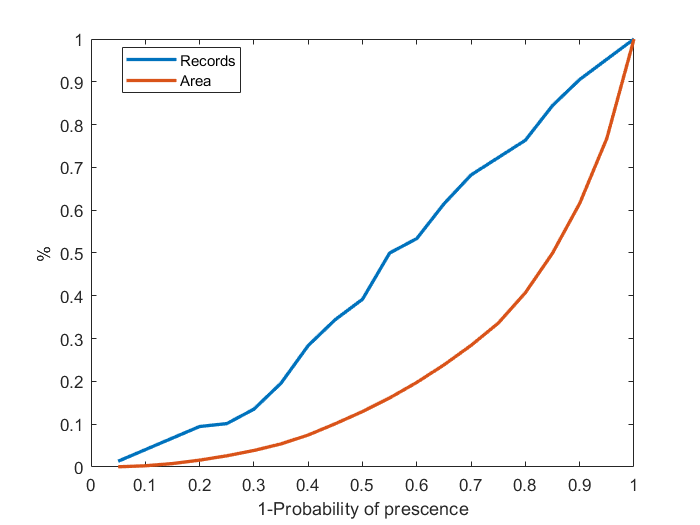

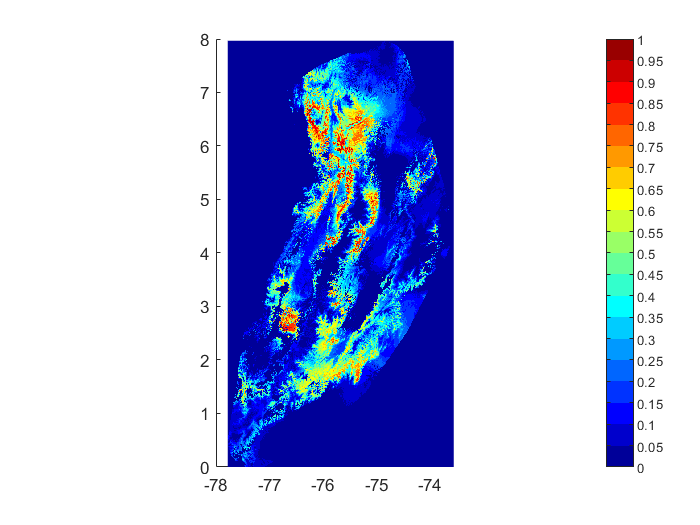

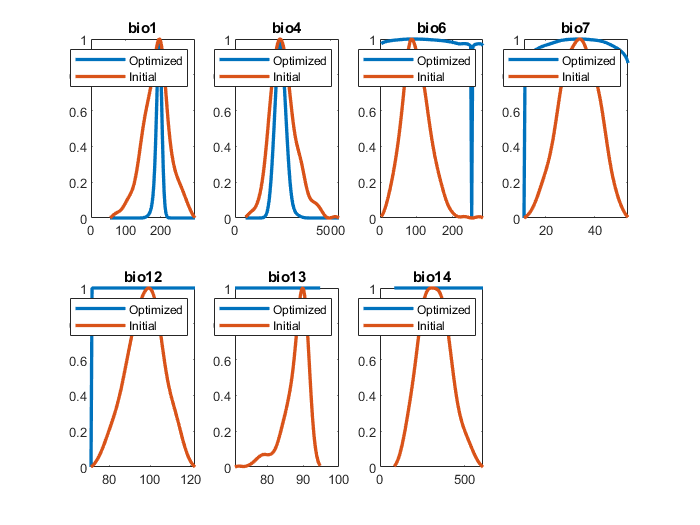

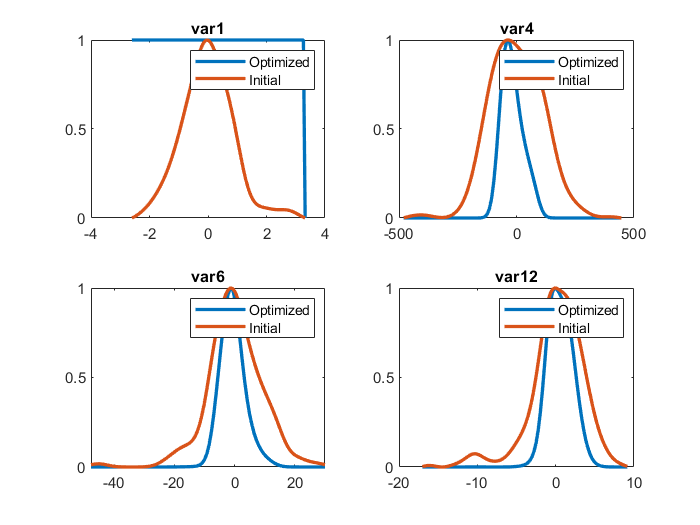

data = struct with fields:
         Tdata: [100×11 table]
    Indicators: [1 4 6 7 12 13 14]
          Vars: [1 4 6 12]
            T2: [148×22 table]
             Z: [956×507×19 double]
             R: [3×2 double]
           Map: [956×507 double]
      Response: [484692×11 double]
      Minimize: 0.8475
        Method: 5
         Coeff: [9.9756 4.2731 0.0054 0.0265 1.3289e-07 0 0 2.3140e-06 10.0000 3.1296 2.9408]
         Optim: 0.2511


data.Method=5;%método para la función a optimizar
parallel=true;%uso del paralelo
solver=2;%1 --> fmincon, otherwise --> particleswarm
data = bnm_optim(data,show,parallel,solver)